#### 采用不同量化因子对同一幅图像压缩

img = imread('Lena.bmp');
QF = 10:5:90;
snrs = zeros(length(QF), 1);
etas = zeros(length(QF), 1);
[h, w] = size(img);
rimgs = zeros(h, w, length(QF), 'uint8');
for i = 1:length(QF)
    [rimg, eta, snr] = jpegsim(img, QF(i));
    etas(i) = eta; snrs(i) = snr;
    rimgs(:,:,i) = rimg;
end

#### 绘制压缩率与PSNR曲线

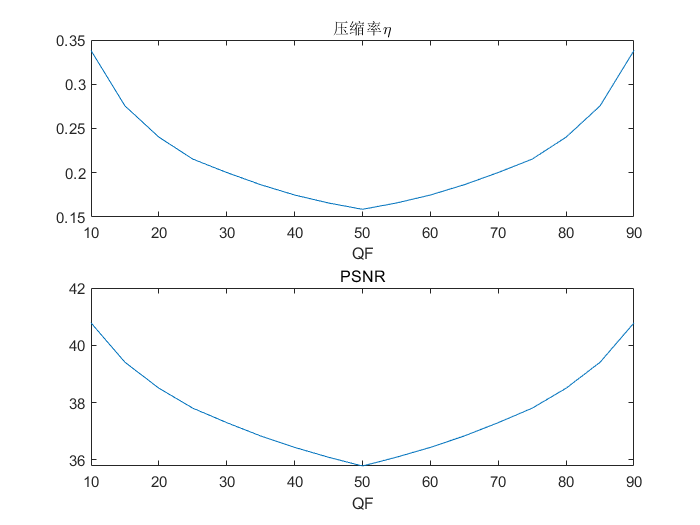

figure;
subplot(211);
plot(QF, etas); title("压缩率\eta"); xlabel("QF");
subplot(212);
plot(QF, snrs); title("PSNR"); xlabel("QF");

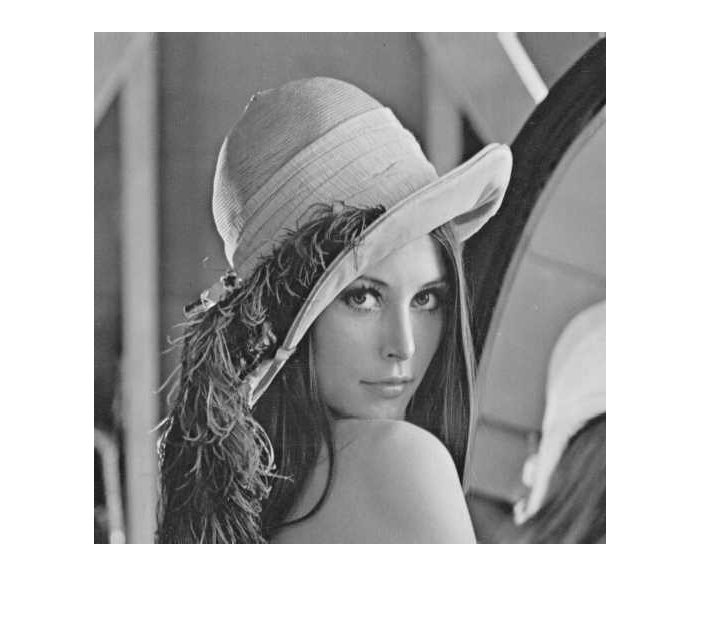

figure;
rimg = rimgs(:,:,round(length(QF)/2));
imshow(rimg); imwrite(rimg, 'rLena.bmp');

#### 采用同一量化因子对不同图像压缩

imgs = {'Cameraman.bmp', 'Goldhill.bmp', 'Lena.bmp','Peppers.bmp'};
snrs = zeros(length(imgs), 1);
etas = zeros(length(imgs), 1);
QF = 50;
for i = 1:length(imgs)
    img = imread(imgs{i});
    [h, w] = size(img);
    [~, eta, snr] = jpegsim(img, QF);
    etas(i) = eta; snrs(i) = snr;
end
[etas snrs]

ans =     0.1844   31.7444
    0.1873   33.5759
    0.1587   35.7846
    0.1604   34.8427
